# Eclipse 🌑🌒🌓

Analyze the total solar eclipse

2024-04-08

## Context

In this tutorial, we will show how to use MATLAB with the SunPy community Python library for Solar Physics

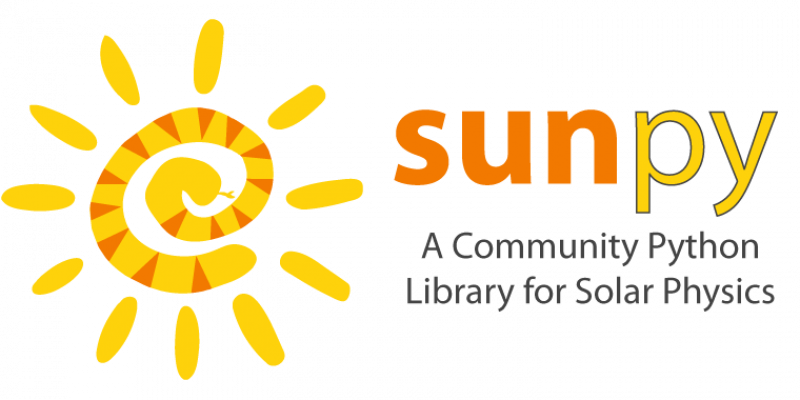

## Resources

- [https://github.com/yanndebray/matlab-with-python-book](https://github.com/yanndebray/matlab-with-python-book)

- [https://docs.sunpy.org/en/stable/generated/gallery/showcase/eclipse_amount.html](https://docs.sunpy.org/en/stable/generated/gallery/showcase/eclipse_amount.html) 

## Set up environment

setup

Defaulting to user installation because normal site-packages is not writeable
Requiremen

pipshow("sunpy")

Name: sunpy
Version: 5.1.2
Summary: SunPy core package: Python for Solar Physics
Home-page: https://sunpy.org
Author: The SunPy Community
Author-email: sunpy@googlegroups.com
License: BSD 2-Clause
Location: /home/matlab/.local/lib/python3.10/site-packages
Requires: astropy, numpy, packaging, parfive, pyerfa
Required-by: 


## Import data with Python live task

% Python code input
pycode2 = [...
"import astropy.units as u",...
"from astropy.coordinates import EarthLocation, solar_system_ephemeris",...
"from astropy.time import Time",...
"from sunpy.coordinates import sun",...
"import numpy as np",...
"import pandas as pd",...
"",...
"location = EarthLocation.from_geodetic(-98.5*u.deg, 29.6*u.deg)",...
"max2023 = Time('2023-10-14 16:54')",...
"max2024 = Time('2024-04-08 18:35')",...
"",...
"time = max2024",...
"",...
"# Define an array of observation times centered around the time of interest",...
"times = time + np.concatenate([np.arange(-120, -5) * u.min,",...
"                                np.arange(-300, 300) * u.s,",...
"                                np.arange(5, 121) * u.min])",...
"",...
"# Create an observer coordinate for the time array",...
"observer = location.get_itrs(times)",...
"",...
"# Calculate the eclipse amounts using a JPL ephemeris",...
"with solar_system_ephemeris.set('de440s'):",...
"    amount = sun.eclipse_amount(observer)",...
"    amount_minimum = sun.eclipse_amount(observer, moon_radius='minimum')",...
"",...
"# Calculate the start/end points of partial/total solar eclipse",...
"partial = np.flatnonzero(amount > 0)",...
"if len(partial) > 0:",...
"    print(""Eclipse detected:"")",...
"    start_partial, end_partial = times[partial[[0, -1]]]",...
"    print(f""  Partial solar eclipse starts at {start_partial} UTC"")",...
"",...
"    total = np.flatnonzero(amount_minimum == 1)",...
"    if len(total) > 0:",...
"        start_total, end_total = times[total[[0, -1]]]",...
"        print(f""  Total solar eclipse starts at {start_total} UTC\n""",...
"                f""  Total solar eclipse ends at {end_total} UTC"")",...
"    print(f""  Partial solar eclipse ends at {end_partial} UTC"")",...
"",...
"df = pd.DataFrame({'time': times.to_datetime(), 'amount': amount, 'amount_minimum': amount_minimum})",...
""...
];

[location, max2023, max2024, time, times, observer, partial, df] = pyrun(pycode2, ...
     [ "location" "max2023" "max2024" "time" "times" "observer" "partial" "df" ])

Eclipse detected:
  Partial solar eclipse starts at 2024-04-08 17:15:00.000 UTC
  Total solar eclipse starts at 2024-04-08 18:33:44.000 UTC
  Total solar eclipse ends at 2024-04-08 18:35:33.000 UTC
  Partial solar eclipse ends at 2024-04-08 19:55:00.000 UTC


location =   Python EarthLocation:

    (-820385.4273935, -5489327.07032871, 3131897.41305728) m


max2023 =   Python Time with properties:

                T: [1x1 py.astropy.time.core.Time]
            cache: [1x1 py.collections.defaultdict]
    delta_ut1_utc: [1x1 py.numpy.ndarray]
           format: [1x3 py.str]
        in_subfmt: [1x1 py.str]
             info: [1x1 py.astropy.time.core.TimeInfo]
         isscalar: 1
              jd1: 2460232
              jd2: 0.2042
             mask: [1x1 py.numpy.ndarray]
           masked: 0
             ndim: [1x1 py.int]
       out_subfmt: [1x1 py.str]
        precision: [1x1 py.int]
            scale: [1x3 py.str]
            shape: [1x0 py.tuple]
             size: [1x1 py.int]
         unmasked: [1x1 py.astropy.time.core.Time]
            value: [1x23 py.str]
        writeable: 1
         location: [1x1 py.NoneType]
           SCALES: [1x7 py.tuple]

    2023-10-14 16:54:00.000


max2024 =   Python Time with properties:

                T: [1x1 py.astropy.time.core.Time]
            cache: [1x1 py.collections.defaultdict]
    delta_ut1_utc: [1x1 py.numpy.ndarray]
           format: [1x3 py.str]
        in_subfmt: [1x1 py.str]
             info: [1x1 py.astropy.time.core.TimeInfo]
         isscalar: 1
              jd1: 2460409
              jd2: 0.2743
             mask: [1x1 py.numpy.ndarray]
           masked: 0
             ndim: [1x1 py.int]
       out_subfmt: [1x1 py.str]
        precision: [1x1 py.int]
            scale: [1x3 py.str]
            shape: [1x0 py.tuple]
             size: [1x1 py.int]
         unmasked: [1x1 py.astropy.time.core.Time]
            value: [1x23 py.str]
        writeable: 1
         location: [1x1 py.NoneType]
           SCALES: [1x7 py.tuple]

    2024-04-08 18:35:00.000


time =   Python Time with properties:

                T: [1x1 py.astropy.time.core.Time]
            cache: [1x1 py.collections.defaultdict]
    delta_ut1_utc: [1x1 py.numpy.ndarray]
           format: [1x3 py.str]
        in_subfmt: [1x1 py.str]
             info: [1x1 py.astropy.time.core.TimeInfo]
         isscalar: 1
              jd1: 2460409
              jd2: 0.2743
             mask: [1x1 py.numpy.ndarray]
           masked: 0
             ndim: [1x1 py.int]
       out_subfmt: [1x1 py.str]
        precision: [1x1 py.int]
            scale: [1x3 py.str]
            shape: [1x0 py.tuple]
             size: [1x1 py.int]
         unmasked: [1x1 py.astropy.time.core.Time]
            value: [1x23 py.str]
        writeable: 1
         location: [1x1 py.NoneType]
           SCALES: [1x7 py.tuple]

    2024-04-08 18:35:00.000


times =   Python Time with properties:

                T: [1x1 py.astropy.time.core.Time]
            cache: [1x1 py.collections.defaultdict]
    delta_ut1_utc: [1x1 py.numpy.ndarray]
           format: [1x3 py.str]
        in_subfmt: [1x1 py.str]
             info: [1x1 py.astropy.time.core.TimeInfo]
         isscalar: 0
              jd1: [1x1 py.numpy.ndarray]
              jd2: [1x1 py.numpy.ndarray]
             mask: [1x1 py.numpy.ndarray]
           masked: 0
             ndim: [1x1 py.int]
       out_subfmt: [1x1 py.str]
        precision: [1x1 py.int]
            scale: [1x3 py.str]
            shape: [1x1 py.tuple]
             size: [1x1 py.int]
         unmasked: [1x1 py.astropy.time.core.Time]
            value: [1x1 py.numpy.ndarray]
        writeable: 0
         location: [1x1 py.NoneType]
           SCALES: [1x7 py.tuple]

    ['2024-04-08 16:35:00.000' '2024-04-08 16:36:00.000'
     '

observer =   Python ITRS with properties:

                                     T: [1x1 py.astropy.coordinates.builtin_frames.itrs.ITRS]
                                 cache: [1x1 py.collections.defaultdict]
                             cartesian: [1x1 py.astropy.coordinates.representation.cartesian.CartesianRepresentation]
                           cylindrical: [1x1 py.astropy.coordinates.representation.cylindrical.CylindricalRepresentation]
                                  data: [1x1 py.astropy.coordinates.representation.cartesian.CartesianRepresentation]
                  default_differential: [1x1 py.abc.ABCMeta]
                default_representation: [1x1 py.abc.ABCMeta]
                     differential_type: [1x1 py.abc.ABCMeta]
                        earth_location: [1x1 py.astropy.coordinates.earth.EarthLocation]
    frame_specific_representation_info: [1x1 py.dict]

partial =   Python ndarray:

    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119   120   121   122   123   124   125   126   127   128   129   130   131   132   133   134   135   136   137   138   139   140   141   142   143   144   145   146   147   148   149   150   151   152   153   154   155   156   157   158   159   160   161   162   163   164   165   166   167   168   169   170   171   172   173   174   175   176   177   178   179   180   181   182   183   184   185   186   187   188 

df =   Python DataFrame with properties:

          T: [1x1 py.pandas.core.frame.DataFrame]
         at: [1x1 py.pandas.core.indexing._AtIndexer]
      attrs: [1x1 py.dict]
       axes: [1x2 py.list]
    columns: [1x1 py.pandas.core.indexes.base.Index]
     dtypes: [1x1 py.pandas.core.series.Series]
      empty: 0
      flags: [1x1 py.pandas.core.flags.Flags]
        iat: [1x1 py.pandas.core.indexing._iAtIndexer]
       iloc: [1x1 py.pandas.core.indexing._iLocIndexer]
      index: [1x1 py.pandas.core.indexes.range.RangeIndex]
        loc: [1x1 py.pandas.core.indexing._LocIndexer]
       ndim: [1x1 py.int]
      shape: [1x2 py.tuple]
       size: [1x1 py.int]
     values: [1x1 py.numpy.ndarray]

                       time  amount  amount_minimum
    0   2024-04-08 16:35:00     0.0             0.0
    1   2024-04-08 16:36:00     0.0             0.0
    2   2024-04-08 16:37:00     0.0             0.


% Clean up
clear pycode2;

## Transform Pandas Dataframe to MATLAB Table

% T = table(df)
TT = timetable(df)

TT = 831x2 timetable
            time            amount    amount_minimum
    ____________________    ______    ______________

    08-Apr-2024 16:35:00      0             0       
    08-Apr-2024 16:36:00      0             0       
    08-Apr-2024 16:37:00      0             0       
    08-Apr-2024 16:38:00      0             0       
    08-Apr-2024 16:39:00      0             0       
    08-Apr-2024 16:40:00      0             0       
    08-Apr-2024 16:41:00      0             0       
    08-Apr-2024 16:42:00      0             0       
    08-Apr-2024 16:43:00      0             0       
    08-Apr-2024 16:44:00      0             0       
    08-Apr-2024 16:45:00      0             0       


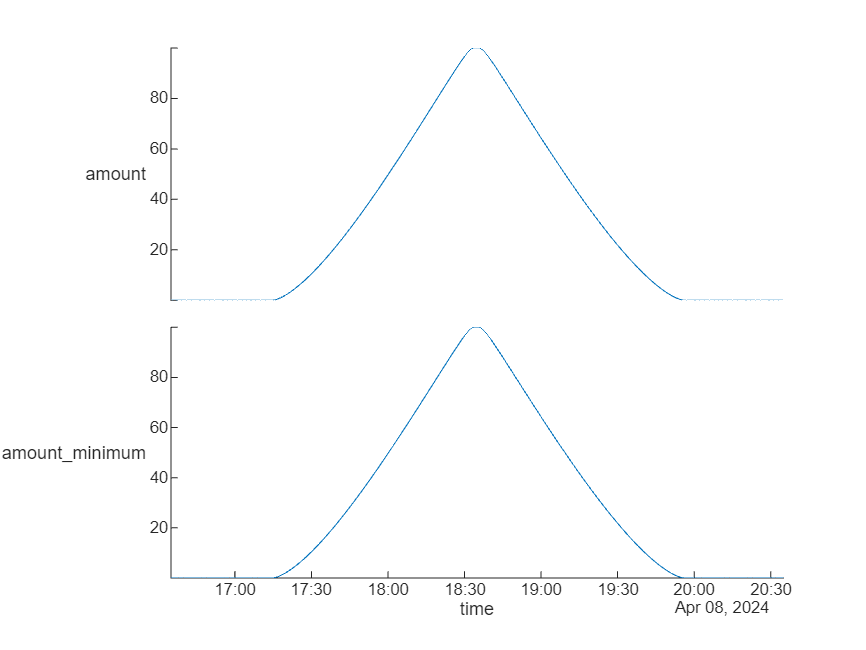

stackedplot(TT)

## Export to ipynb and md

export('livescript.mlx','README.md');
export('livescript.mlx','notebook.ipynb');